# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 7.6.4 Rain Attenuation

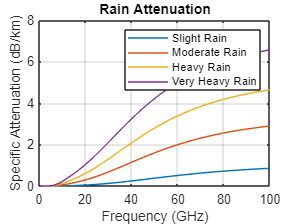

clear

% Operating frequency (GHz)
frequency = linspace(1.0, 100);

% Rain rate (mm/hr)
rain_rate = 0.5;

% Elevation angle (deg)
elevation_angle = 10.0;

% Polarization tilt angle (deg)
polarization_tilt_angle = 0;

% Calculate the rain attenuation
slight = rain_attenuation(frequency, rain_rate, elevation_angle, polarization_tilt_angle);

% Rain rate (mm/hr)
rain_rate = 3.0;

% Calculate the rain attenuation
moderate = rain_attenuation(frequency, rain_rate, elevation_angle, polarization_tilt_angle);

% Rain rate (mm/hr)
rain_rate = 6.0;

% Calculate the rain attenuation
heavy = rain_attenuation(frequency, rain_rate, elevation_angle, polarization_tilt_angle);

% Rain rate (mm/hr)
rain_rate = 10.0;

% Calculate the rain attenuation
very_heavy = rain_attenuation(frequency, rain_rate, elevation_angle, polarization_tilt_angle);

% Plot the results
figure;
plot(frequency, slight); hold on
plot(frequency, moderate);
plot(frequency, heavy);
plot(frequency, very_heavy);
title('Rain Attenuation');
xlabel('Frequency (GHz)');
ylabel('Specific Attenuation (dB/km)');
legend('Slight Rain', 'Moderate Rain', 'Heavy Rain', 'Very Heavy Rain');
grid on;